## Задание 1. Исследование свойств многоканальной системы.

function observable(C, A)
    Ob = obsv(A, C)
    rank_Ob = rank(Ob)
    if rank_Ob == size(A, 1)
        fprintf('YES\n');
    else
        fprintf('NO\n');
    end
end
function controllable(A, B)
    Co = ctrb(A, B)
    rank_Co = rank(Co)
    if rank_Co == size(A, 1)
        fprintf('YES\n');
    else
        fprintf('NO\n');
    end
end

A = [0 1; 1 1];
B = [1 2; 1 4];
C = [2 -1; 1 -4];
eig(A)

ans =    -0.6180
    1.6180


syms s;
I = eye(size(A, 1));
W = C*(s*I-A)^(-1)*B;
Wsimp = simplify(W);
vpa(Wsimp, 4)

$$ans = \left(\begin{array}{cc} -\frac{1.0\,\left(s-1.0\right)}{-1.0\,s^{2}+s+1.0} & -\frac{2.0}{-1.0\,s^{2}+s+1.0}\\ \frac{3.0\,s+4.0}{-1.0\,s^{2}+s+1.0} & \frac{2.0\,\left(7.0\,s+3.0\right)}{-1.0\,s^{2}+s+1.0} \end{array}\right)$$

det(W)

$$ans = \frac{14}{-s^{2}+s+1}$$

[num, den] = numden(W);
num = sym(num); % Нули
den = sym(den); % Полюса
solution = solve(num,s);
vpa(solution, 4)

 
ans =
 
Empty sym: 0-by-1
 


solution = solve(den,s);
vpa(solution, 4)

$$ans = \left(\begin{array}{c} -0.618\\ 1.618 \end{array}\right)$$

controllable(A, B)

Co =      1     2     1     4
     1     4     2     6


rank_Co = 2

YES


observable(C, A)

Ob =      2    -1
     1    -4
    -1     1
    -4    -3


rank_Ob = 2

YES


U_out = [C * ctrb(A, B), zeros(2, 2)]

U_out =      1     0     0     2     0     0
    -3   -14    -7   -20     0     0


rank_output_ctrb = rank(U_out)

rank_output_ctrb = 2

Wn = sym(zeros(2, 4));
tm = 1;
for i = 1:2
    for j = 1:2
        Ww = W(i, j);
        [num, den] = numden(W(i, j));
        [residues, poles, direct_term] = residue(sym2poly(num), sym2poly(den));

        % Вывод результатов
        disp('Разложение на простейшие дроби:');
        sym_result = sym(0); % Инициализируем символьное выражение
        for k = 1:length(residues)
            % Преобразуем числовые residues и poles в символьные
            residue_k = sym(residues(k));
            pole_k = sym(poles(k));
            % Добавляем дробь вида residue_k / (s - pole_k)
            term = residue_k / (s - pole_k);

            Wn(k, tm) = vpa(term, 4);

            sym_result = sym_result + term;
        end
        
        % Если есть прямой член, добавляем его
        if ~isempty(direct_term)
            sym_result = sym_result + sym(direct_term);
        end
        
        % Выводим результат в символьной форме
        vpa(sym_result, 4)

        tm = tm + 1;
        
       
    end
end

Разложение на простейшие дроби:


$$ans = \frac{0.7236}{s+0.618}+\frac{0.2764}{s-1.618}$$

Разложение на простейшие дроби:


$$ans = \frac{0.8944}{s-1.618}-\frac{0.8944}{s+0.618}$$

Разложение на простейшие дроби:


$$ans = \frac{0.9597}{s+0.618}-\frac{3.96}{s-1.618}$$

Разложение на простейшие дроби:


$$ans = -\frac{1.186}{s+0.618}-\frac{12.81}{s-1.618}$$


vpa(Wn, 4)

$$ans = \left(\begin{array}{cccc} \frac{0.2764}{s-1.618} & \frac{0.8944}{s-1.618} & -\frac{3.96}{s-1.618} & -\frac{12.81}{s-1.618}\\ \frac{0.7236}{s+0.618} & -\frac{0.8944}{s+0.618} & \frac{0.9597}{s+0.618} & -\frac{1.186}{s+0.618} \end{array}\right)$$

t = 0:0.01:4;
ep = [0.2764 0.8944  -3.96 -12.81; 0.7236 -0.8944 0.9597 -1.186]

ep =     0.2764    0.8944   -3.9600  -12.8100
    0.7236   -0.8944    0.9597   -1.1860


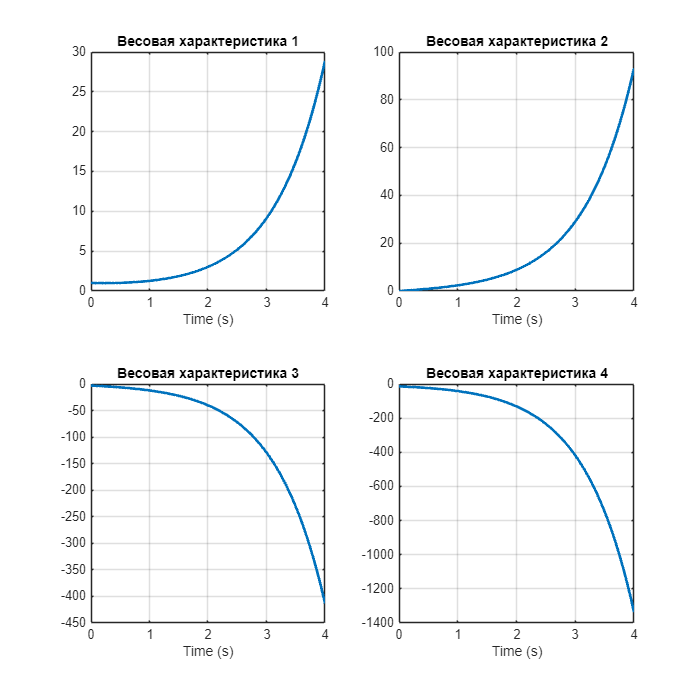

figure('Position', [0 0 700 700]);
m = 2; % Number of rows
n = 2; % Number of columns    plot(t, ep(1, i) * exp(t * 1.1618) + ep(2, i) * exp(t * -0.618), 'Linewidth', 2);

for i = 1:4
    subplot(m, n, i);
    plot(t, ep(1, i) * exp(t * 1.1618) + ep(2, i) * exp(t * -0.618), 'Linewidth', 2);
    title(['Весовая характеристика ', int2str(i)]);
    xlabel('Time (s)');
    grid on;
end
exportgraphics(gcf, ['figs/1_ir.png'], 'Resolution', 500);

syms t
for i = 1:4
    vpa(ep(1, i) * exp(t * 1.1618) + ep(2, i) * exp(t * -0.618), 4)
end

$$ans = 0.2764\,{\mathrm{e}}^{1.162\,t}+0.7236\,{\mathrm{e}}^{-0.618\,t}$$

$$ans = 0.8944\,{\mathrm{e}}^{1.162\,t}-0.8944\,{\mathrm{e}}^{-0.618\,t}$$

$$ans = 0.9597\,{\mathrm{e}}^{-0.618\,t}-3.96\,{\mathrm{e}}^{1.162\,t}$$

$$ans = -12.81\,{\mathrm{e}}^{1.162\,t}-1.186\,{\mathrm{e}}^{-0.618\,t}$$

Wn = sym(zeros(2, 4));
tm = 1;
for i = 1:2
    for j = 1:2
        Ww = W(i, j) / s;
        [num, den] = numden(Ww);
        [residues, poles, direct_term] = residue(sym2poly(num), sym2poly(den));

        % Вывод результатов
        disp('Разложение на простейшие дроби:');
        sym_result = sym(0); % Инициализируем символьное выражение
        for k = 1:length(residues)
            % Преобразуем числовые residues и poles в символьные
            residue_k = sym(residues(k));
            pole_k = sym(poles(k));
            % Добавляем дробь вида residue_k / (s - pole_k)
            term = residue_k / (s - pole_k);

            Wn(k, tm) = vpa(term, 4);

            sym_result = sym_result + term;
        end
        
        % Если есть прямой член, добавляем его
        if ~isempty(direct_term)
            sym_result = sym_result + sym(direct_term);
        end
        
        % Выводим результат в символьной форме
        vpa(sym_result, 4)

        tm = tm + 1;
        
       
    end
end

Разложение на простейшие дроби:


$$ans = \frac{0.1708}{s-1.618}-\frac{1.171}{s+0.618}+\frac{1}{s}$$

Разложение на простейшие дроби:


$$ans = \frac{1.447}{s+0.618}+\frac{0.5528}{s-1.618}-\frac{2.0}{s}$$

Разложение на простейшие дроби:


$$ans = \frac{4.0}{s}-\frac{2.447}{s-1.618}-\frac{1.553}{s+0.618}$$

Разложение на простейшие дроби:


$$ans = \frac{1.919}{s+0.618}-\frac{7.919}{s-1.618}+\frac{6.0}{s}$$

t = 0:0.01:4;
vpa(Wn, 4)

$$ans = \left(\begin{array}{cccc} \frac{0.1708}{s-1.618} & \frac{0.5528}{s-1.618} & -\frac{2.447}{s-1.618} & -\frac{7.919}{s-1.618}\\ -\frac{1.171}{s+0.618} & \frac{1.447}{s+0.618} & -\frac{1.553}{s+0.618} & \frac{1.919}{s+0.618}\\ \frac{1}{s} & -\frac{2.0}{s} & \frac{4.0}{s} & \frac{6.0}{s} \end{array}\right)$$

ep = [0.1708 0.5528  -2.447 -7.919; -1.171 1.447 -1.553 1.919; 1 -2 4 6]

ep =     0.1708    0.5528   -2.4470   -7.9190
   -1.1710    1.4470   -1.5530    1.9190
    1.0000   -2.0000    4.0000    6.0000


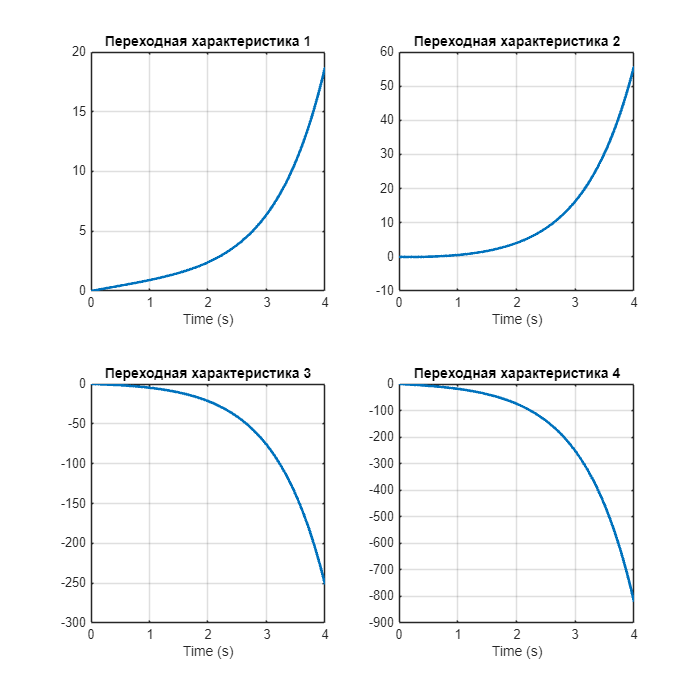


figure('Position', [0 0 700 700]);
m = 2; % Number of rows
n = 2; % Number of columns

for i = 1:4
    subplot(m, n, i);
    plot(t, ep(1, i) * exp(t * 1.1618) + ep(2, i) * exp(t * -0.618) + ep(3, i), 'Linewidth', 2);
    title(['Переходная характеристика ', int2str(i)]);
    xlabel('Time (s)');
    grid on;
end
exportgraphics(gcf, ['figs/1_sr.png'], 'Resolution', 500);

syms t
for i = 1:4
    vpa(ep(1, i) * exp(t * 1.1618) + ep(2, i) * exp(t * -0.618) + ep(3, i), 4)
end

$$ans = 0.1708\,{\mathrm{e}}^{1.162\,t}-1.171\,{\mathrm{e}}^{-0.618\,t}+1.0$$

$$ans = 0.5528\,{\mathrm{e}}^{1.162\,t}+1.447\,{\mathrm{e}}^{-0.618\,t}-2.0$$

$$ans = 4.0-1.553\,{\mathrm{e}}^{-0.618\,t}-2.447\,{\mathrm{e}}^{1.162\,t}$$

$$ans = 1.919\,{\mathrm{e}}^{-0.618\,t}-7.919\,{\mathrm{e}}^{1.162\,t}+6.0$$

syms s omega real;
Wf = subs(W, s, 1i*omega);
simplify(Wf)

$$ans = \begin{array}{l} \left(\begin{array}{cc} -\frac{\omega^{3}\,\mathrm{i}+2\,\omega \,\mathrm{i}-1}{\sigma_{1}} & -\frac{2\,\omega^{2}-2\,\omega \,\mathrm{i}+2}{\sigma_{1}}\\ \frac{3\,\omega^{3}\,\mathrm{i}+7\,\omega^{2}-\omega \,\mathrm{i}+4}{\sigma_{1}} & \frac{14\,\omega^{3}\,\mathrm{i}+20\,\omega^{2}+8\,\omega \,\mathrm{i}+6}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\omega^{4}+3\,\omega^{2}+1 \end{array}$$

Wn = sym(zeros(2, 4));
tm = 1;
for i = 1:2
    for j = 1:2
        Ww = Wf(i, j);
        Wn(1, tm) = simplify(real(Ww));
        Wn(2, tm) = simplify(imag(Ww)); % Мнимая часть
        tm = tm + 1;
    end
end

vpa(Wn, 4)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \frac{1}{\sigma_{1}} & -\frac{2.0\,\left(\omega^{2}+1.0\right)}{\sigma_{2}} & \frac{7.0\,\omega^{2}+4.0}{\sigma_{1}} & \frac{2.0\,\left(10.0\,\omega^{2}+3.0\right)}{\sigma_{1}}\\ -\frac{1.0\,\omega \,\left(\omega^{2}+2.0\right)}{\sigma_{1}} & \frac{2.0\,\omega }{\sigma_{2}} & \frac{\omega \,\left(3.0\,\omega^{2}-1.0\right)}{\sigma_{1}} & \frac{2.0\,\omega \,\left(7.0\,\omega^{2}+4.0\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\omega^{4}+3.0\,\omega^{2}+1.0\\ \sigma_{2}={\left(\omega^{2}+1.0\right)}^{2}+\omega^{2} \end{array}$$

Ah = sym(zeros(1, 4));
Ph = sym(zeros(1, 4));
Lah = Ah;

for i = 1:4
    Ah(i) = simplify(sqrt(Wn(1, i)^2 + Wn(2, i)^2));
    Ph(i) = simplify(atan2(Wn(1, i), Wn(2, i)));
    Lah(i) = 20 * log10(Ah(i));
end
vpa(Ah, 4)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \frac{\sqrt{{\left|\omega \right|}^{2}\,{\left(\omega^{2}+2.0\right)}^{2}+1.0}}{\sigma_{1}} & \frac{2.0}{\sqrt{\sigma_{1}}} & \frac{\sqrt{9.0\,\omega^{6}+43.0\,\omega^{4}+57.0\,\omega^{2}+16.0}}{\sigma_{1}} & \frac{2.0\,\sqrt{49.0\,\omega^{2}+9.0}}{\sqrt{\sigma_{1}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\omega^{4}+3.0\,\omega^{2}+1.0 \end{array}$$

vpa(Ph, 4)

$$ans = \left(\begin{array}{cccc} \text{atan2}\left(1.0,-1.0\,\omega^{3}-2.0\,\omega \right) & \text{atan2}\left(-1.0\,\omega^{2}-1.0,\omega \right) & \text{atan2}\left(7.0\,\omega^{2}+4.0,\omega \,\left(3.0\,\omega^{2}-1.0\right)\right) & \text{atan2}\left(\frac{1.0\,\left(10.0\,\omega^{2}+3.0\right)}{7.0\,\omega^{2}+4.0},\omega \right) \end{array}\right)$$

vpa(Lah, 4)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} 8.686\,\log\left(\frac{\sqrt{{\left|\omega \right|}^{2}\,{\left(\omega^{2}+2.0\right)}^{2}+1.0}}{\sigma_{1}}\right) & 8.686\,\log\left(\frac{2.0}{\sqrt{\sigma_{1}}}\right) & 8.686\,\log\left(\frac{\sqrt{9.0\,\omega^{6}+43.0\,\omega^{4}+57.0\,\omega^{2}+16.0}}{\sigma_{1}}\right) & 8.686\,\log\left(\frac{2.0\,\sqrt{49.0\,\omega^{2}+9.0}}{\sqrt{\sigma_{1}}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\omega^{4}+3.0\,\omega^{2}+1.0 \end{array}$$

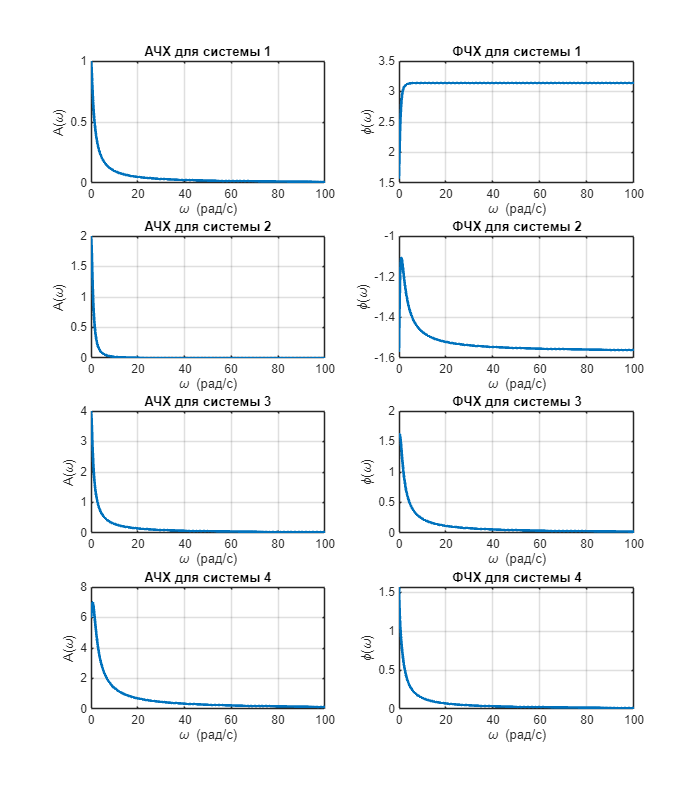

Lph = Ph;

omega_vals = logspace(-1, 1, 100); % Диапазон частот от 0.1 до 10
omega_v = 0:0.1:100;

figure('Position', [0, 0, 700, 800]); % Create a large figure for AЧХ and ФЧХ
for i = 1:4
    % Compute values for AЧХ and ФЧХ
    A_vals = double(subs(Ah(i), omega, omega_v));
    P_vals = double(subs(Ph(i), omega, omega_v));
    
    % Plot АЧХ
    subplot(4, 2, 2 * (i - 1) + 1);
    plot(omega_v, A_vals, 'LineWidth', 2);
    grid on;
    xlabel('\omega (рад/с)');
    ylabel('A(\omega)');
    title(['АЧХ для системы ' int2str(i)]);
    
    % Plot ФЧХ
    subplot(4, 2, 2 * (i - 1) + 2);
    plot(omega_v, P_vals, 'LineWidth', 2);
    grid on;
    xlabel('\omega (рад/с)');
    ylabel('\phi(\omega)');
    title(['ФЧХ для системы ' int2str(i)]);
end
exportgraphics(gcf, 'figs/combined_A_P_freq.png', 'Resolution', 500);

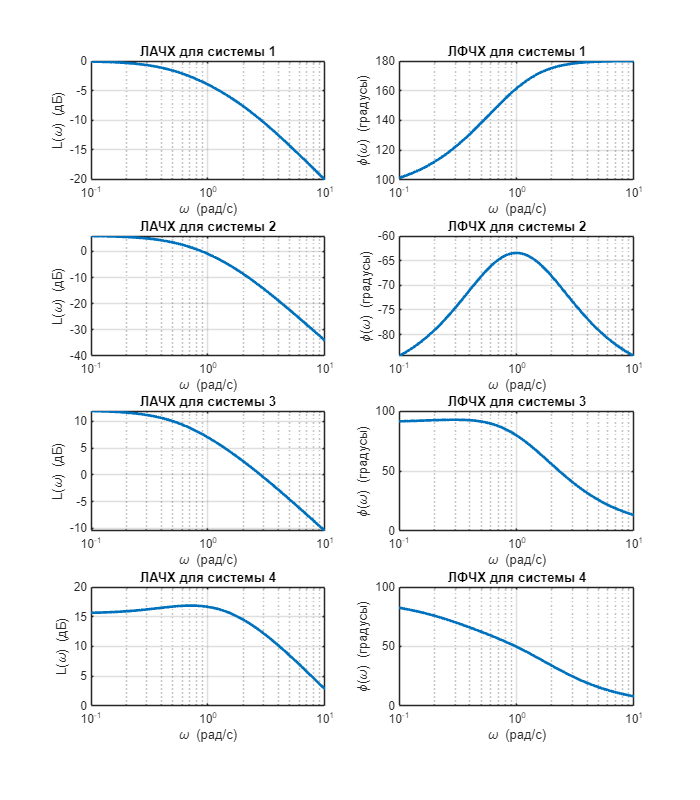


figure('Position', [0, 0, 700, 800]); % Create a large figure for ЛАЧХ and ЛФЧХ
for i = 1:4
    % Compute values for ЛАЧХ and ЛФЧХ
    L_vals = double(subs(Lah(i), omega, omega_vals));
    phi_vals = double(subs(Ph(i), omega, omega_vals)) * 180 / pi;
    
    % Plot ЛАЧХ
    subplot(4, 2, 2 * (i - 1) + 1);
    semilogx(omega_vals, L_vals, 'LineWidth', 2);
    grid on;
    xlabel('\omega (рад/с)');
    ylabel('L(\omega) (дБ)');
    title(['ЛАЧХ для системы ' int2str(i)]);
    
    % Plot ЛФЧХ
    subplot(4, 2, 2 * (i - 1) + 2);
    semilogx(omega_vals, phi_vals, 'LineWidth', 2);
    grid on;
    xlabel('\omega (рад/с)');
    ylabel('\phi(\omega) (градусы)');
    title(['ЛФЧХ для системы ' int2str(i)]);
end
exportgraphics(gcf, 'figs/combined_L_P_logfreq.png', 'Resolution', 500);

A = [0 1; 1 1];       % 3x3
B = [1 2; 1 4];                     % 3x1
Bf = [1 2; -2 4];          % 3x2
C = [2 -1; 1 -4];                      % 1x3
D = [1 0; 0 -1];                            % 1x1
Df = [-1 0; 0 1];                         % 1x2
Cz = [3 1; -2 4];
Dz = [1 0; 0 1];

x0 = [1; 1];

t = 0:0.01:10;
f1 = [3 * cos(t); 11 * sin(3 * t)];
f2 = [sin(3 * t); 8 * cos(t)];
g = [3 * cos(6 * t); sin(6*t)];

controllable(A, B)

Co =      1     2     1     4
     1     4     2     6


rank_Co = 2

YES


observable(C, A)

Ob =      2    -1
     1    -4
    -1     1
    -4    -3


rank_Ob = 2

YES


observable(Cz, A)

Ob =      3     1
    -2     4
     1     4
     4     2


rank_Ob = 2

YES


Uy = [C * ctrb(A, B), D]

Uy =      1     0     0     2     1     0
    -3   -14    -7   -20     0    -1


rank(Uy)

ans = 2

Uz = [C * ctrb(A, B), Dz]

Uz =      1     0     0     2     1     0
    -3   -14    -7   -20     0     1


rank(Uz)

ans = 2

syms s

W = C * (s * eye(2) - A)^-1 * B + D;
simplify(W)

$$ans = \left(\begin{array}{cc} -\frac{s^{2}-2}{-s^{2}+s+1} & -\frac{2}{-s^{2}+s+1}\\ \frac{3\,s+4}{-s^{2}+s+1} & \frac{s^{2}+13\,s+5}{-s^{2}+s+1} \end{array}\right)$$

det(W)

$$ans = \frac{s^{2}+14\,s+18}{-s^{2}+s+1}$$


W = Cz * (s * eye(2) - A)^-1 * B + Dz;
simplify(W)

$$ans = \left(\begin{array}{cc} -\frac{s\,\left(s+3\right)}{-s^{2}+s+1} & -\frac{2\,\left(5\,s+4\right)}{-s^{2}+s+1}\\ -\frac{2\,\left(s+2\right)}{-s^{2}+s+1} & -\frac{s^{2}+11\,s+3}{-s^{2}+s+1} \end{array}\right)$$

det(W)

$$ans = -\frac{s^{2}+15\,s+32}{-s^{2}+s+1}$$

Gamma_w = [
    0 -6 0 0 0 0;
    6 0 0 0 0 0;
    0 0 0 -1 0 0;
    0 0 1 0 0 0;
    0 0 0 0 0 -3;
    0 0 0 0 3 0];
Yg = [3/2 3/2 0 0 0 0;
    -1/2 1/2 0 0 0 0];
Y1 = [0 0 0 3 0 0;
    0 0 0 0 0 11];
Y2 = [0 0 0 0 0 1;
    0 0 0 8 0 0];
w0 = [1; 1; 0; 1; 1; 0];

syms t
simplify(Yg * expm(Gamma_w * t) * w0)

$$ans = \left(\begin{array}{c} 3\,\cos\left(6\,t\right)\\ \sin\left(6\,t\right) \end{array}\right)$$

syms t
simplify(Y1 * expm(Gamma_w * t) * w0)

$$ans = \left(\begin{array}{c} 3\,\cos\left(t\right)\\ 11\,\sin\left(3\,t\right) \end{array}\right)$$

syms t
simplify(Y2 * expm(Gamma_w * t) * w0)

$$ans = \left(\begin{array}{c} \sin\left(3\,t\right)\\ 8\,\cos\left(t\right) \end{array}\right)$$

sym(Yg)

$$ans = \left(\begin{array}{cccccc} \frac{3}{2} & \frac{3}{2} & 0 & 0 & 0 & 0\\ -\frac{1}{2} & \frac{1}{2} & 0 & 0 & 0 & 0 \end{array}\right)$$

sym(Y1)

$$ans = \left(\begin{array}{cccccc} 0 & 0 & 0 & 3 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 11 \end{array}\right)$$

sym(Y2)

$$ans = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 8 & 0 & 0 \end{array}\right)$$

sym(Gamma_w)

$$ans = \left(\begin{array}{cccccc} 0 & -6 & 0 & 0 & 0 & 0\\ 6 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & -1 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & -3\\ 0 & 0 & 0 & 0 & 3 & 0 \end{array}\right)$$

eig(A)

ans =    -0.6180
    1.6180


controllable(A, B);

Co =      1     2     1     4
     1     4     2     6


rank_Co = 2

YES


G1 = diag([-1, -2]);
Yy = [1 1; 1 1];
observable(Yy, G1);

Ob =      1     1
     1     1
    -1    -2
    -1    -2


rank_Ob = 2

YES


BY = B*Yy

BY =      3     3
     5     5


rank(B*Yy)

ans = 1


% Декомпозиция BY = b*h
[U, S, V] = svd(BY); % Сингулярное разложение
b = U(:, 1) * sqrt(S(1, 1)); % Вектор b
h = sqrt(S(1, 1)) * V(:, 1)'; % Вектор h
disp('Вектор b:');

Вектор b:


vpa(sym(b), 4)

$$ans = \left(\begin{array}{c} -1.477\\ -2.462 \end{array}\right)$$

disp('Вектор h:');

Вектор h:


vpa(sym(h), 4)

$$ans = \left(\begin{array}{cc} -2.031 & -2.031 \end{array}\right)$$

% Проверка управляемости (A, b)
controllable(A, b);

Co =    -1.4774   -2.4624
   -2.4624   -3.9398


rank_Co = 2

YES


% Проверка наблюдаемости (h, Gamma)
observable(h, G1);

Ob =    -2.0305   -2.0305
    2.0305    4.0611


rank_Ob = 2

YES


cvx_begin sdp quiet;
    variable P(2,2);
    A*P-P*G1 == B*Yy;
cvx_end;

K = -Yy*pinv(P)

K =    -3.0000    1.0000
   -3.0000    1.0000


eig(A+B*K)

ans =    -2.0000
   -1.0000


syms s;
I = eye(size(A, 1));
W = C*(s*I-A)^(-1)*B;
Wsimp = simplify(W);
vpa(Wsimp, 4)

$$ans = \left(\begin{array}{cc} -\frac{1.0\,\left(s-1.0\right)}{-1.0\,s^{2}+s+1.0} & -\frac{2.0}{-1.0\,s^{2}+s+1.0}\\ \frac{3.0\,s+4.0}{-1.0\,s^{2}+s+1.0} & \frac{2.0\,\left(7.0\,s+3.0\right)}{-1.0\,s^{2}+s+1.0} \end{array}\right)$$

det(W)

$$ans = \frac{14}{-s^{2}+s+1}$$

[num, den] = numden(det(W));
num = sym(num); % Нули
den = sym(den); % Полюса
solution = solve(num,s);
vpa(solution, 4)

 
ans =
 
Empty sym: 0-by-1
 


eig_G = eigs(Gamma_w)

eig_G =    0.0000 + 6.0000i
   0.0000 - 6.0000i
   0.0000 + 3.0000i
   0.0000 - 3.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i


for e = eig_G'
    rank([A - eye(2) * e B; Cz Dz])
end

ans = 4

ans = 4

ans = 4

ans = 4

ans = 4

ans = 4


n = size(A, 1);      % 3
m_g = size(Gamma_w, 1); % 2
cvx_begin sdp quiet
    variable P(n, m_g) % 3x2
    variable Kw(2, m_g) % 1x2
    % Уравнения Франсиса-Дэвисона для слежения
    P * Gamma_w - (A + B * K) * P - Bf * Y1 == B*Kw;        % 3x2
    (Cz + Dz*K) * P + Dz * Kw == Yg;             % 1x2
cvx_end
vpa(sym(Kw), 4)

$$ans = \left(\begin{array}{cccccc} 1.846 & 0.9709 & 0.9207 & -1.103 & 0.7236 & -6.236\\ -0.2012 & 0.6522 & -3.377 & 9.979 & 4.781 & -9.777 \end{array}\right)$$

Kb = [Kw K]

Kb =     1.8457    0.9709    0.9207   -1.1029    0.7236   -6.2365   -3.0000    1.0000
   -0.2012    0.6522   -3.3769    9.9789    4.7807   -9.7768   -3.0000    1.0000


Ab = [Gamma_w zeros(6,2)
    Bf*Y1 A];
Bb = [zeros(6,2); B];
Cb = [Df*Y2-Yg  C];

sym(Ab)

$$ans = \left(\begin{array}{cccccccc} 0 & -6 & 0 & 0 & 0 & 0 & 0 & 0\\ 6 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & -1 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & -3 & 0 & 0\\ 0 & 0 & 0 & 0 & 3 & 0 & 0 & 0\\ 0 & 0 & 0 & 3 & 0 & 22 & 0 & 1\\ 0 & 0 & 0 & -6 & 0 & 44 & 1 & 1 \end{array}\right)$$

sym(Bb)

$$ans = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 1 & 2\\ 1 & 4 \end{array}\right)$$

sym(Cb)

$$ans = \left(\begin{array}{cccccccc} -\frac{3}{2} & -\frac{3}{2} & 0 & 0 & 0 & -1 & 2 & -1\\ \frac{1}{2} & -\frac{1}{2} & 0 & 8 & 0 & 0 & 1 & -4 \end{array}\right)$$

eig(Ab)

ans =    0.0000 + 6.0000i
   0.0000 - 6.0000i
  -0.0000 + 1.0000i
  -0.0000 - 1.0000i
  -0.6180 + 0.0000i
   1.6180 + 0.0000i
   0.0000 + 3.0000i
   0.0000 - 3.0000i


G5 = diag([-1, -2, -3, -4, -5, -6, -7, -8]);
sym(G5)

$$ans = \left(\begin{array}{cccccccc} -1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & -2 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -3 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & -4 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & -5 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & -6 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & -7 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & -8 \end{array}\right)$$

Y5 = ones(8, 2);
sym(Y5)

$$ans = \left(\begin{array}{cc} 1 & 1\\ 1 & 1\\ 1 & 1\\ 1 & 1\\ 1 & 1\\ 1 & 1\\ 1 & 1\\ 1 & 1 \end{array}\right)$$

cvx_begin quiet;
    variable Q(8,8);
    G5*Q-Q*Ab == Y5*Cb;
cvx_end;
L = pinv(Q)*Y5

L =   -15.7797  -15.7797
  -17.9851  -17.9851
   -3.8753   -3.8753
    0.8105    0.8105
    1.4528    1.4528
    1.4662    1.4662
   56.8363   56.8363
   52.8553   52.8553


vpa(sym(L),4)

$$ans = \left(\begin{array}{cc} -15.78 & -15.78\\ -17.99 & -17.99\\ -3.875 & -3.875\\ 0.8105 & 0.8105\\ 1.453 & 1.453\\ 1.466 & 1.466\\ 56.84 & 56.84\\ 52.86 & 52.86 \end{array}\right)$$

eig(Ab+L*Cb)

ans =    -8.0000
   -7.0000
   -6.0000
   -5.0000
   -4.0000
   -3.0000
   -2.0000
   -1.0000


xf0 = [w0; x0];
xf0_hat = zeros(8, 1);

tspan = 0:0.01:20;

z0 = [w0; x0; zeros(8,1)];  % x1: w(6), x(2), hat_w(4), hat_x(2)

%% Функция управления
u = @(t, z) Kw * z(9:14) + K * z(15:16);

%% Функция динамики
ode_obs = @(t, z) [
    Ab * z(1:8) + Bb * u(t, z); ... % Истинная система
     Ab * z(9:16) + Bb * u(t, z) ...
     + L * (Cb * z(9:16) - Cb * z(1:8))];

%% Решение
[t, z] = ode45(ode_obs, tspan, z0);

x = z(:,7:8)';
w = z(:,1:6)';
w_hat = z(:,9:14)';
x_hat = z(:,15:16)';

u = K * x_hat + Kw * w_hat;
f1 = Y1 * w;
f2 = Y2 * w;
g = Yg * w;

y = Cb * [w; x] + D * u;
z = Cz * x + Dz * u - g;
e = g - y;

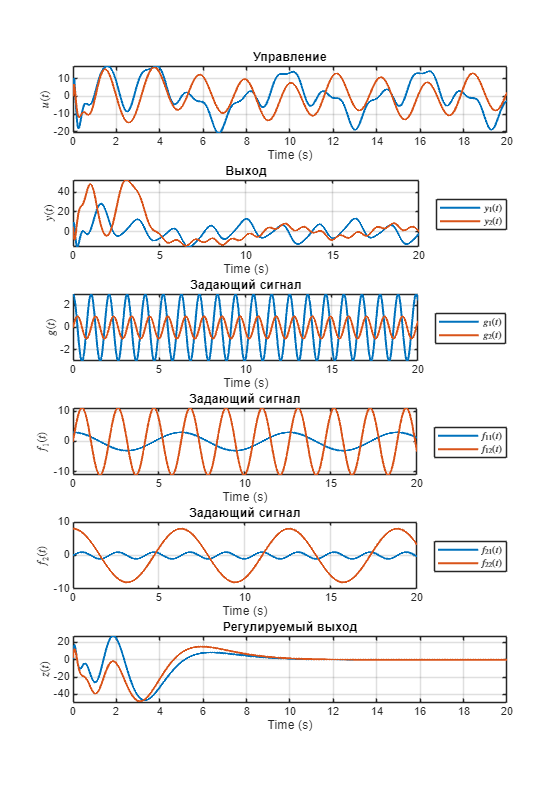

figure('Position', [0 0 700 1000]);
m = 6; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(t, u, 'LineWidth', 1.5); hold on;
title('Управление');
xlabel('Time (s)');
ylabel('$u(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 2);
plot(t, y, 'LineWidth', 1.5); hold on;
legend({'$y_1(t)$', '$y_2(t)$'}, 'Location', 'eastoutside', 'Interpreter', 'latex');
title('Выход');
xlabel('Time (s)');
ylabel('$y(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 3);
plot(t, g, 'LineWidth', 1.5);
legend({'$g_1(t)$', '$g_2(t)$'}, 'Location', 'eastoutside', 'Interpreter', 'latex');
title('Задающий сигнал');
xlabel('Time (s)');
ylabel('$g(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 4);
plot(t, f1, 'LineWidth', 1.5);
legend({'$f_{11}(t)$', '$f_{12}(t)$'}, 'Location', 'eastoutside', 'Interpreter', 'latex');
title('Задающий сигнал');
xlabel('Time (s)');
ylabel('$f_1(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 5);
plot(t, f2, 'LineWidth', 1.5);
legend({'$f_{21}(t)$', '$f_{22}(t)$'}, 'Location', 'eastoutside', 'Interpreter', 'latex');
title('Задающий сигнал');
xlabel('Time (s)');
ylabel('$f_2(t)$', 'Interpreter', 'latex');
grid on;

subplot(m, n, 6);
plot(t, z, 'LineWidth', 1.5); hold on;
title('Регулируемый выход');
xlabel('Time (s)');
ylabel('$z(t)$', 'Interpreter', 'latex');
grid on;
exportgraphics(gcf, ['figs/2fig.png'], 'Resolution', 500);

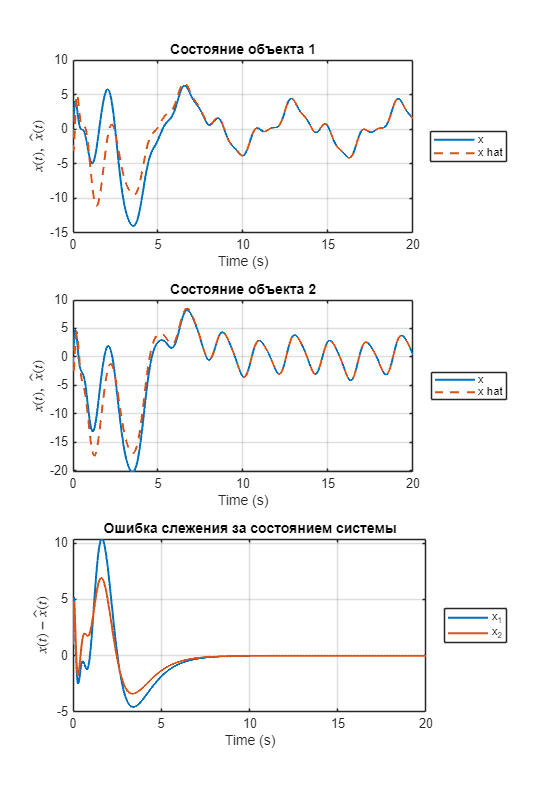

figure('Position', [0 0 700 1000]);
m = 3; % Number of rows
n = 1; % Number of columns

for i=1:2
    subplot(m, n, i);
    plot(t, x(i, :), 'LineWidth', 1.5); hold on;
    plot(t, x_hat(i, :), '--', 'LineWidth', 1.5);
    title(['Состояние объекта ' int2str(i)]);
    legend({'x', 'x hat'}, 'Location', 'eastoutside');
    xlabel('Time (s)');
    ylabel('$x(t),\ \hat x(t)$', 'Interpreter', 'latex');
    grid on;
end

subplot(m, n, 3);
plot(t, x - x_hat, 'LineWidth', 1.5); hold on;
title('Ошибка слежения за состоянием системы');
xlabel('Time (s)');
ylabel('$x(t)-\hat x(t)$', 'Interpreter', 'latex');
legend({'x_1', 'x_2'}, 'Location', 'eastoutside');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/2fig1.png'], 'Resolution', 500);

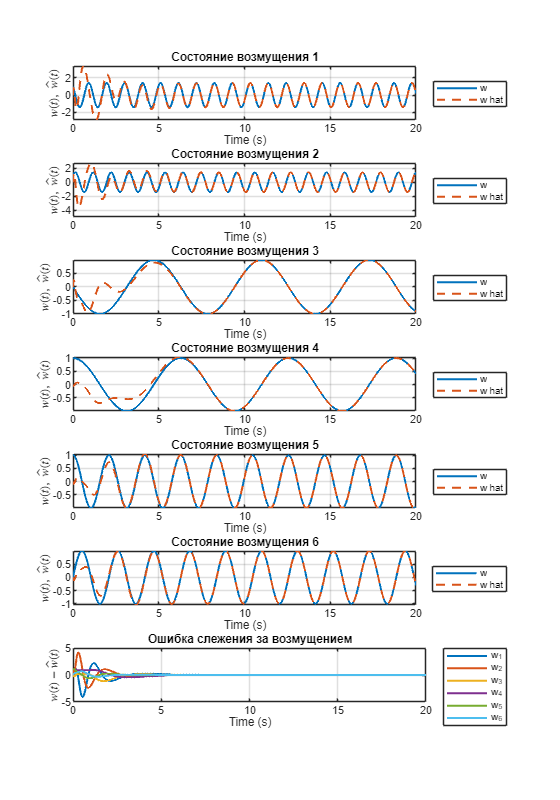

figure('Position', [0 0 700 1000]);
m = 7; % Number of rows
n = 1; % Number of columns

for i=1:6
    subplot(m, n, i);
    plot(t, w(i, :), 'LineWidth', 1.5); hold on;
    plot(t, w_hat(i, :), '--', 'LineWidth', 1.5);
    title(['Состояние возмущения ' int2str(i)]);
    legend({'w', 'w hat'}, 'Location', 'eastoutside');
    xlabel('Time (s)');
    ylabel('$w(t),\ \hat w(t)$', 'Interpreter', 'latex');
    grid on;
end

subplot(m, n, 7);
plot(t, w - w_hat, 'LineWidth', 1.5); hold on;
title('Ошибка слежения за возмущением');
xlabel('Time (s)');
ylabel('$w(t)-\hat w(t)$', 'Interpreter', 'latex');
legend({'w_1', 'w_2', 'w_3', 'w_4', 'w_5', 'w_6'}, 'Location', 'eastoutside');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/2fig2.png'], 'Resolution', 500);